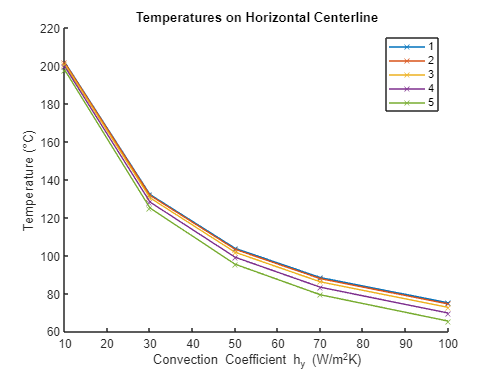

Tdata(:, :, 1) = readmatrix('hy=10.xls');
Tdata(:, :, 2) = readmatrix('hy=30.xls');
Tdata(:, :, 3) = readmatrix('hy=50.xls');
Tdata(:, :, 4) = readmatrix('hy=70.xls');
Tdata(:, :, 5) = readmatrix('hy=100.xls');

hvals = [10 30 50 70 100];

VertLines = [];
HorizLines = [];

for ind = 1:5
    h = hvals(ind);
    T = Tdata(:, :, ind);
    [m,n] = size(T);
    
    mid_m = (1 + m)/2;
    mid_n = (1 + n)/2;

    pointX = linspace(m,1, 5);
    pointY = ones(1,5) .* mid_n;
    VertPoints = interp2(T, pointY, pointX);
    VertLines = [VertLines VertPoints'];

    pointX = ones(1,5) .* mid_m;
    pointY = linspace(1,n, 5);
    HorizPoints = interp2(T, pointY, pointX);
    HorizLines = [HorizLines HorizPoints'];
end

f1 = figure;
hold on
for ind = 1:5
    plot(hvals, HorizLines(ind,:), 'x-')
end
legend('1', '2', '3', '4', '5');
title('Temperatures on Horizontal Centerline')
xlabel('Convection Coefficient h_{y} (W/m^2K)')
ylabel('Temperature (°C)') 

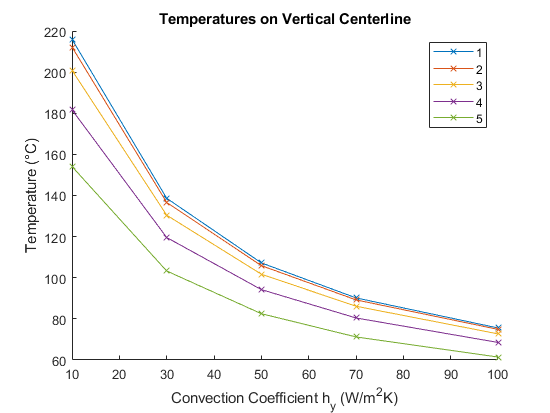


f2 = figure;
hold on
for ind = 1:5
    plot(hvals, VertLines(ind,:), 'x-')
end
legend('1', '2', '3', '4', '5');
title('Temperatures on Vertical Centerline')
xlabel('Convection Coefficient h_{y} (W/m^2K)')
ylabel('Temperature (°C)') 